# Data Analysis

## Piano inclinato

% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 9×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'h2'}      0.412       0.001       {'MTR'}
     {'h1'}      1.122       0.001       {'MTR'}
     {'s1'}      1.992       0.001       {'MTR'}
     {'s2'}      0.713       0.001       {'MTR'}
     {'m1'}      15.19        0.01       {'GRM'}
     {'m2'}      98.82        0.01       {'GRM'}
     {'m3'}      130.6        0.01       {'GRM'}
     {'m4'}      13.79        0.01       {'GRM'}
     {'m5'}       26.6        0.01       {'GRM'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 200×5 table
    index     mass      t      uncertainty      uom  
    _____    ______    ____    ___________    _______

      1      {'m1'}    1.65       0.01        {'SEC'}
      2      {'m1'}     1.6       0.01        {'SEC'}
      3      {'m1'}    1.66       0.01        {'SEC'}
      4      {'m1'}    2.18       0.01        {'SEC'}
      5      {'m1'}    1.54       0.01        {'SEC'}
      6      {'m1'}    1.74       0.01        {'SEC'}
      7      {'m1'}    1.47       0.01        {'SEC'}
      8      {'m1'}    1.55       0.01        {'SEC'}
      9      {'m1'}     1.8       0.01        {'SEC'}
     10      {'m1'}    1.75       0.01        {'SEC'}
     11      {'m1'}    1.94       0.01        {'SEC'}
     12      {'m1'}    2.05       0.01        {'SEC'}
     13      {'m1'}    2.67       0.01        {'SEC'}
 

tools=readtable("..\data\tools.csv")

tools = 3×3 table
         tool          uncertainty      uom  
    _______________    ___________    _______

    {'Flessometro'}       0.001       {'MTR'}
    {'Bilancia'   }        0.01       {'GRM'}
    {'Cronometro' }        0.01       {'SEC'}


## defining variables

% uncertainty
ds=tools.uncertainty(1);
dt=tools.uncertainty(3);
dg=0.01;

% creating masses array
m=unique(df2.mass);
lm=length(m);

% gravitational acceleration
g=9.81;

% tempi
t1=df2.t(1:40,:);
t2=df2.t(41:80,:);
t3=df2.t(81:120,:);
t4=df2.t(121:160,:);
t5=df2.t(161:200,:);

% space
s1=df1.value(3);
s2=df1.value(4);

% height
h2=df1.value(1);
h1=df1.value(2);

% general variable
n=length(t1);

% number of bins
nb=6;

## plotting

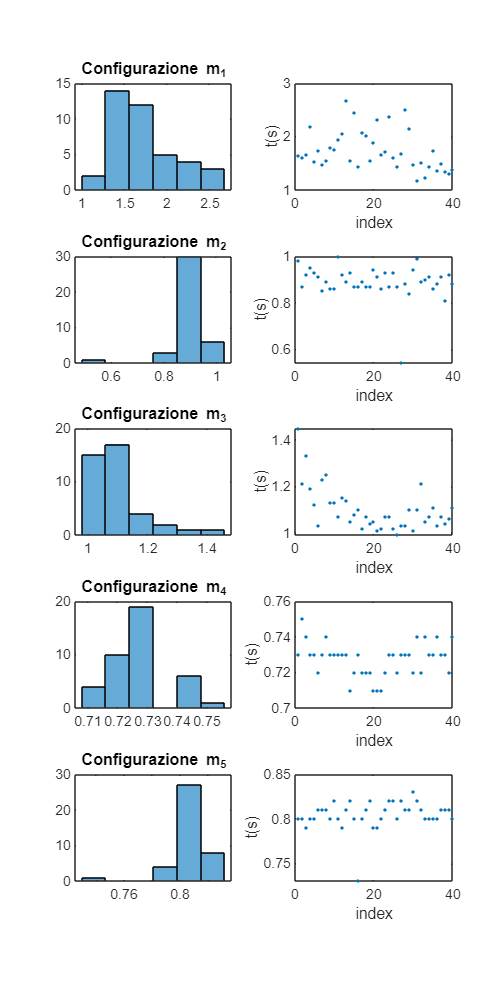

% small multiples
grid=figure;
subplot(5,2,1)
histogram(t1,nb)
title('Configurazione m_1')
subplot(5,2,2)
plot(1:40,t1,".")
ylabel('t(s)')
xlabel('index')
subplot(5,2,3)
histogram(t2,nb)
title('Configurazione m_2')
subplot(5,2,4)
plot(1:40,t2,".")
ylabel('t(s)')
xlabel('index')
subplot(5,2,5)
histogram(t3,nb)
title('Configurazione m_3')
subplot(5,2,6)
plot(1:40,t3,".")
ylabel('t(s)')
xlabel('index')
subplot(5,2,7)
histogram(t4,nb)
title('Configurazione m_4')
subplot(5,2,8)
plot(1:40,t4,".")
ylabel('t(s)')
xlabel('index')
subplot(5,2,9)
histogram(t5,nb)
title('Configurazione m_5')
subplot(5,2,10)
plot(1:40,t5,".")
ylabel('t(s)')
xlabel('index')
grid.Position=[10 10 800 1600]; % [left bottom width height]

## calculating

% average time
tm1=mean(t1);
tm2=mean(t2);
tm3=mean(t3);
tm4=mean(t4);
tm5=mean(t5);

% creating array tm
tm=[tm1;tm2;tm3;tm4;tm5];

% space
s=s1-s2;

% height
h=h1-h2;

% angle
rteta=asin(h./s); %rad
dteta=(180./pi)*rteta; %deg

% creating empty array
a=zeros(lm,1);      % acceleration
da=zeros(lm,1);     % error acceleration
rea=zeros(lm,1);    % relative error (acceleration)
mu=zeros(lm,1);     % coefficient of friction
dmu=zeros(lm,1);    % error coefficient of friction
rec=zeros(lm,1);    % relative error (coefficient)
cfra=zeros(lm,1);   % position first significant value (acceleration)
cfr=zeros(lm,1);
uoma=string(zeros(lm,1));  % uom acceleration

% multiply ds*2 because s=s1-s2
ds=ds.*2;

for i=1:lm

    % calculating accelerations
    a(i)=(2.*s)/((tm(i)).^2);

    % calculating coefficient of friction
    mu(i)=tan(rteta)-(a(i)./g.*cos(rteta));
    
    % propagation of uncertainty acceleration
    da(i)=(2.*(ds+(4.*s.*dt)))./(tm(i).^2);
    
    % propagation of uncertainty coefficient
    dmu(i)=(((2.*ds)/(((cos(rteta)).^2)*sqrt(s.^2-h^2))).*(1-((a(i).*sin(rteta))./g)).*(1+(h./s)))+((2.*(ds+(4.*s.*dt)))./((tm(i).^2).*g.*cos(rteta)))+((a(i).*dg)./((g.^2).*cos(rteta)));
    
    % rounding values
    cfr(i)=-floor(log10(dmu(i)));
    dmu(i)=round(dmu(i),cfr(i));
    mu(i)=round(mu(i),cfr(i));
    cfra(i)=-floor(log10(da(i)));
    da(i)=round(da(i),cfra(i));
    a(i)=round(a(i),cfra(i));
    
    % relative error
    rea(i)=(da(i)/a(i))*100;
    rea(i)=round(rea(i),2);
    rec(i)=(dmu(i)./mu(i))*100;
    rec(i)=round(rec(i),2);

    % uom
    uoma(i)="MSK";
end


% significant digits
as=string(zeros(lm,1));     %acceleration significant digits (temp)
mus=string(zeros(lm,1));    %mu significant digits (temp)

for i=1:lm
    as(i)=sprintf(strcat('%.',num2str(cfra(i)),'f'),round(a(i),cfra(i)));
    mus(i)=sprintf(strcat('%.',num2str(cfr(i)),'f'),round(mu(i),cfr(i)));
end

% converting a,mu,rea,rec array to string
a=string(a);
mu=string(mu);
rea=string(rea);
rec=string(rec);

% substituting values
for i=1:lm
    a(i)=as(i);
    mu(i)=mus(i);
    rec(i)=sprintf('%.2f',rec(i));
    rea(i)=sprintf('%.2f',rea(i));
end

% creating output array
acceleration=array2table(string(horzcat(string(m),a,da,uoma,rea)),"VariableNames",{'configuration','acceleration','uncertainty','uom','relative_error'})

acceleration = 5×5 table
    configuration    acceleration    uncertainty     uom     relative_error
    _____________    ____________    ___________    _____    ______________

        "m1"            "0.85"         "0.04"       "MSK"        "4.71"    
        "m2"            "3.2"          "0.1"        "MSK"        "3.13"    
        "m3"            "2.11"         "0.09"       "MSK"        "4.27"    
        "m4"            "4.8"          "0.2"        "MSK"        "4.17"    
        "m5"            "4.0"          "0.2"        "MSK"        "5.00"    


coefficient=array2table(string(horzcat(string(m),mu,dmu,rec)),'VariableNames',{'configuration','coefficient_friction','uncertainty','relative_error'})

coefficient = 5×4 table
    configuration    coefficient_friction    uncertainty    relative_error
    _____________    ____________________    ___________    ______________

        "m1"                "0.60"             "0.01"          "1.67"     
        "m2"                "0.39"             "0.02"          "5.13"     
        "m3"                "0.49"             "0.02"          "4.08"     
        "m4"                "0.26"             "0.03"          "11.54"    
        "m5"                "0.33"             "0.03"          "9.09"     


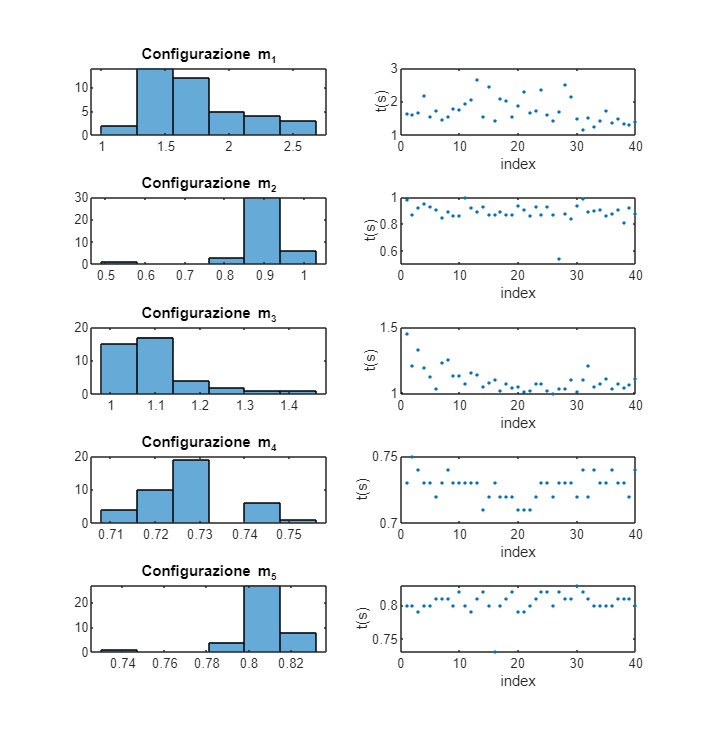

% exporting csv
writetable(acceleration,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(coefficient,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(grid,'..\img\plot-1.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);